# compare the scores for different viewing angles 

% read in object tables 

global DEFAULT_MATFILE_DIR
load([DEFAULT_MATFILE_DIR '/cosmic_jellyfish_objectTable.mat'],'objectTableComp');


## plot scores

Here are the distributions for the total number of classifications and yes scores for the entire classification table, after removing the training annd review samples but before enforcing the dates.

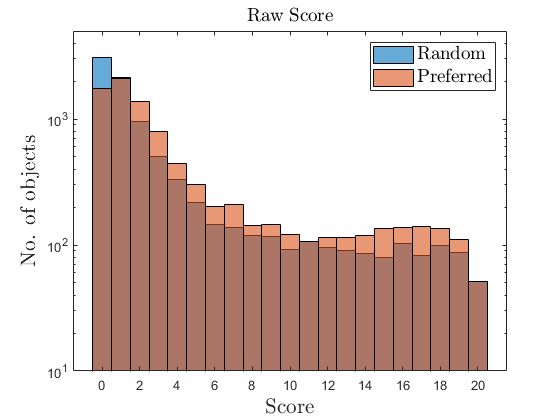

figure
histogram(objectTableComp.scoreRawRand)
hold on 
histogram(objectTableComp.scoreRawPref)
legend('Random','Preferred','Interpreter','latex','fontsize',14);
set(gca,'yscale','log')
ylim([10 5e3])
xlabelmine('Score');
ylabelmine('No. of objects');
titlemine('Raw Score');

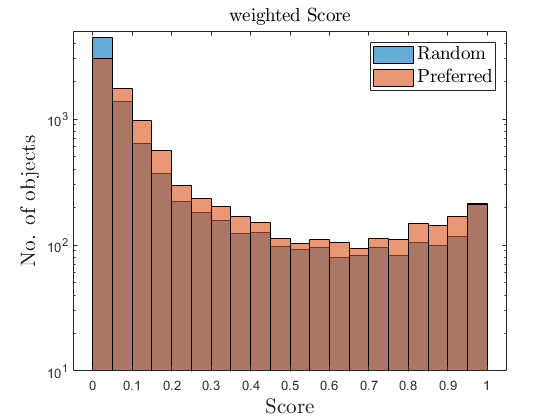


figure
histogram(objectTableComp.scoreWeightedRand)
hold on 
histogram(objectTableComp.scoreWeightedPref)
legend('Random','Preferred','Interpreter','latex','fontsize',14);
set(gca,'yscale','log')
ylim([10 5e3])
xlabelmine('Score');
ylabelmine('No. of objects');
titlemine('weighted Score');

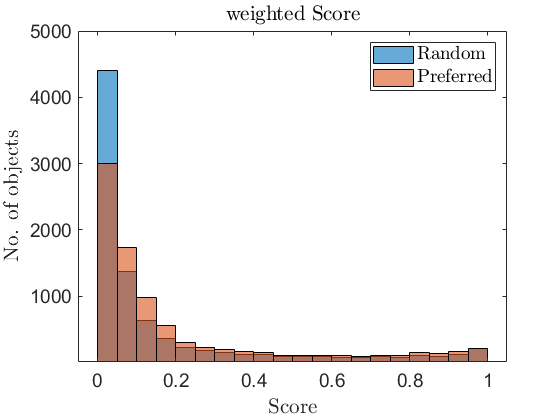


figure
histogram(objectTableComp.scoreWeightedRand)
hold on 
histogram(objectTableComp.scoreWeightedPref)
legend('Random','Preferred','Interpreter','latex','fontsize',14);
%set(gca,'yscale','log')
set(gca,'fontsize',14)
ylim([10 5e3])
xlabelmine('Score');
ylabelmine('No. of objects');
titlemine('weighted Score');

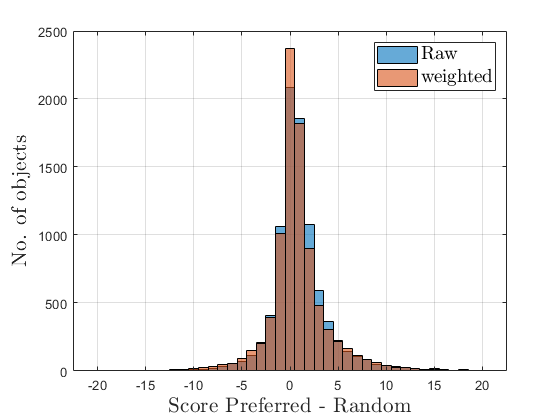


figure
histogram(objectTableComp.scoreRawPref-objectTableComp.scoreRawRand,-20.5:1:20.5)
hold on
histogram(objectTableComp.scoreWeightedPref.*20-objectTableComp.scoreWeightedRand.*20,-20.5:1:20.5)%,-17.5:0.5:17.5)
grid
%set(gca,'yscale','log')
legend('Raw','weighted','Interpreter','latex','fontsize',14);
xlabelmine('Score Preferred - Random');
ylabelmine('No. of objects');

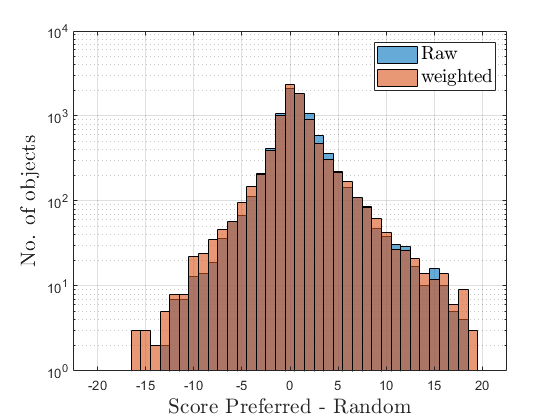


figure
histogram(objectTableComp.scoreRawPref-objectTableComp.scoreRawRand,-20.5:1:20.5)
hold on
histogram(objectTableComp.scoreWeightedPref.*20-objectTableComp.scoreWeightedRand.*20,-20.5:1:20.5)%,-17.5:0.5:17.5)
grid
set(gca,'yscale','log')
legend('Raw','weighted','Interpreter','latex','fontsize',14);
xlabelmine('Score Preferred - Random');
ylabelmine('No. of objects');

Raw score Stats

scR=objectTableComp.scoreRawRand;
scP=objectTableComp.scoreRawPref;
ng=height(objectTableComp);
fprintf('Number of objects in random/preferred comparison: %i \n',ng)

Number of objects in random/preferred comparison: 8762 


fprintf('No. of objects with higher scores in preferred : %i , %3.1f %% \n',...
    sum(scP>scR),sum(scP>scR)/ng*100)

No. of objects with higher scores in preferred : 4657 , 53.1 % 


fprintf('No. of objects with lower scores in preferred: %i , %3.1f %%\n',...
    sum(scP<scR),sum(scP<scR)/ng*100)

No. of objects with lower scores in preferred: 2021 , 23.1 %


fprintf('No. of objects with equal scores in preferred: %i , %3.1f %%\n',...
    sum(scP==scR),sum(scP==scR)/ng*100)

No. of objects with equal scores in preferred: 2084 , 23.8 %


fprintf('No. of objects which are JF in preferred: %i , %3.1f %%\n',...
    sum(scP>=16),sum(scP>=16 )/ng*100)

No. of objects which are JF in preferred: 574 , 6.6 %


fprintf('No. of objects which are JF in random : %i , %3.1f %%\n',...
    sum(scR>=16),sum( scR>=16)/ng*100)

No. of objects which are JF in random : 423 , 4.8 %


fprintf('increase is  : %3.1f %%\n',...
    (sum(scP>=16)./sum(scR>=16)-1).*100)

increase is  : 35.7 %


fprintf('No. of objects which are JF in preferred but not in random: %i , %3.1f %%\n',...
    sum(scP>=16 & scR<16),sum(scP>=16 & scR<16)/ng*100)

No. of objects which are JF in preferred but not in random: 262 , 3.0 %


fprintf('No. of objects which are JF in random but not in preferred: %i , %3.1f %%\n',...
    sum(scP<16 & scR>=16),sum(scP<16 & scR>=16)/ng*100)

No. of objects which are JF in random but not in preferred: 111 , 1.3 %


Weighted score stats

scR=objectTableComp.scoreWeightedRand;
scP=objectTableComp.scoreWeightedPref;
ng=height(objectTableComp);
fprintf('Number of objects in random/preferred comparison: %i \n',ng)

Number of objects in random/preferred comparison: 8762 


fprintf('No. of objects with higher scores in preferred : %i , %3.1f %% \n',...
    sum(scP>scR),sum(scP>scR)/ng*100)

No. of objects with higher scores in preferred : 4839 , 55.2 % 


fprintf('No. of objects with lower scores in preferred: %i , %3.1f %%\n',...
    sum(scP<scR),sum(scP<scR)/ng*100)

No. of objects with lower scores in preferred: 2592 , 29.6 %


fprintf('No. of objects with equal scores in preferred: %i , %3.1f %%\n',...
    sum(scP==scR),sum(scP==scR)/ng*100)

No. of objects with equal scores in preferred: 1331 , 15.2 %


fprintf('No. of objects which are JF in preferred: %i , %3.1f %%\n',...
    sum(scP>=0.8),sum(scP>=0.8 )/ng*100)

No. of objects which are JF in preferred: 671 , 7.7 %


fprintf('No. of objects which are JF in random : %i , %3.1f %%\n',...
    sum(scR>=0.8),sum( scR>=0.8)/ng*100)

No. of objects which are JF in random : 532 , 6.1 %


fprintf('increase is  : %3.1f %%\n',...
    (sum(scP>=0.8)./sum(scR>=0.8)-1).*100)

increase is  : 26.1 %


fprintf('No. of objects which are JF in preferred but not in random: %i , %3.1f %%\n',...
    sum(scP>=0.8 & scR<0.8),sum(scP>=0.8 & scR<0.8)/ng*100)

No. of objects which are JF in preferred but not in random: 275 , 3.1 %


fprintf('No. of objects which are JF in random but not in preferred: %i , %3.1f %%\n',...
    sum(scP<0.8 & scR>=0.8),sum(scP<0.8 & scR>=0.8)/ng*100)

No. of objects which are JF in random but not in preferred: 136 , 1.6 %


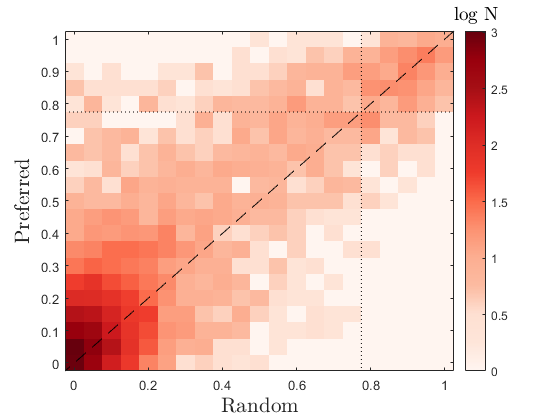

scR=objectTableComp.scoreRawRand./20;
scP=objectTableComp.scoreRawPref./20;


[bird, binsize, xl,yl]= histogram2d(scR,scP,ones(size(scR)),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([-0.5 21]./20,[-0.5 21]./20,'--k')
plot([15.5 15.5]./20,[-0.5 21]./20,':k')
plot([-0.5 21]./20,[15.5 15.5]./20,':k')
xlabelmine('Random');
ylabelmine('Preferred');
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;
barTitle(hb,'log N')

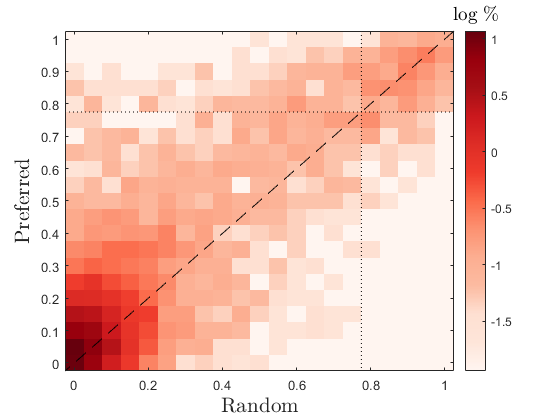

titlemine('Raw Score');

figure
imagesc(xl,yl,log10(bbird./sum(sum(bbird)).*100))
hold on
plot([-0.5 21]./20,[-0.5 21]./20,'--k')
plot([15.5 15.5]./20,[-0.5 21]./20,':k')
plot([-0.5 21]./20,[15.5 15.5]./20,':k')
xlabelmine('Random');
ylabelmine('Preferred');
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;
barTitle(hb,'log \%')

titlemine('Raw Score');


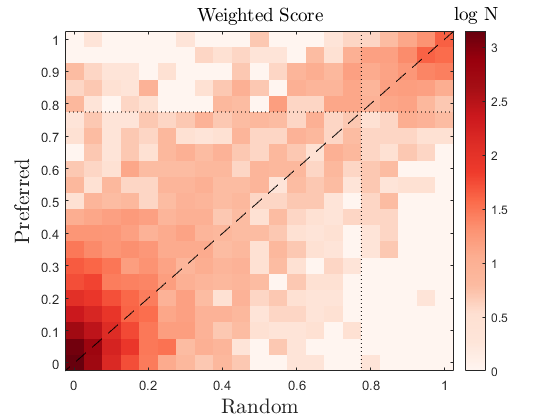

scR=objectTableComp.scoreWeightedRand;
scP=objectTableComp.scoreWeightedPref;


[bird, binsize, xl,yl]= histogram2d(scR,scP,ones(size(scR)),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([-0.5 21]./20,[-0.5 21]./20,'--k')
plot([15.5 15.5]./20,[-0.5 21]./20,':k')
plot([-0.5 21]./20,[15.5 15.5]./20,':k')
xlabelmine('Random');
ylabelmine('Preferred');
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;
barTitle(hb,'log N')
titlemine('Weighted Score');

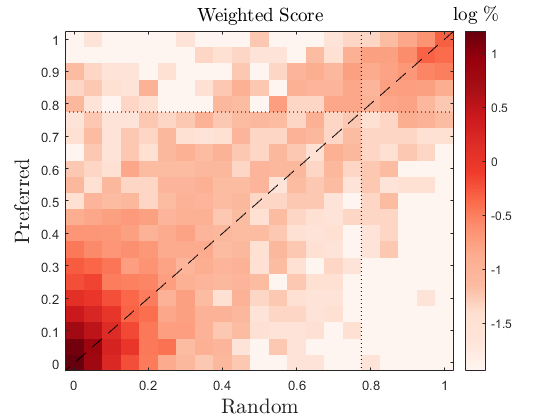


figure
imagesc(xl,yl,log10(bbird./sum(sum(bbird)).*100))
hold on
plot([-0.5 21]./20,[-0.5 21]./20,'--k')
plot([15.5 15.5]./20,[-0.5 21]./20,':k')
plot([-0.5 21]./20,[15.5 15.5]./20,':k')
xlabelmine('Random');
ylabelmine('Preferred');
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;
barTitle(hb,'log \%')
titlemine('Weighted Score');

Raw Scores

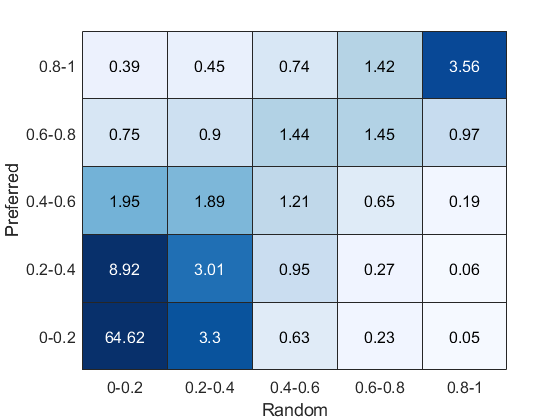

scR=objectTableComp.scoreRawRand./20;
scP=objectTableComp.scoreRawPref./20;

figure
edj=0:0.2:1;
edj(end)=1.01;
len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((scP>=edj(i) & scP<edj(i+1)) & ...
            (scR>=edj(j) & scR<edj(j+1)) );
    end
end
 
 cdata=cdata./ng.*100;
 cdata= round(cdata.*100)/100;
 lab={'0-0.2' '0.2-0.4' '0.4-0.6' '0.6-0.8' '0.8-1'};
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
caxis([0 4 ])
colorbar('off')
colormap(brewermap(256,'Blues'))
ht.xlabel('Random')
ht.ylabel('Preferred')
ht.FontSize=12;

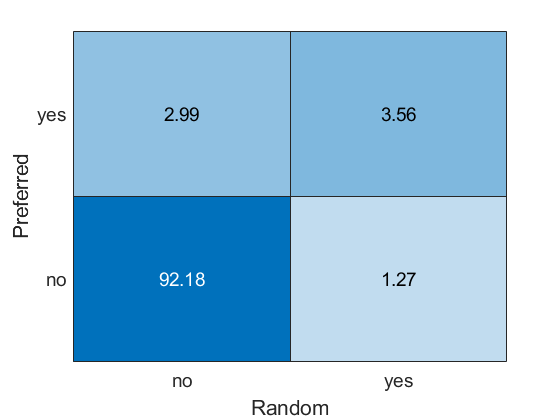



jfThresh=0.8;
jfCJF=scP>=jfThresh;
jf50=scR>=jfThresh;



jfdata=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./ng*100;
jfdata= round(jfdata.*100)/100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 8])
colorbar('off')
ht.xlabel('Random')
ht.ylabel('Preferred')

fprintf("total agreement on what is or isn't JF (score>=%s)= %s %% \n",...
   num2str(jfThresh), num2str(jfdata(1,2)+jfdata(2,1)))

total agreement on what is or isn't JF (score>=0.8)= 95.74 % 




fprintf("Number of PhaseI JF (score>=%s)= %s (%s %%) \n",...
   num2str(jfThresh), num2str((ng/100.*(jfdata(2,2)+jfdata(1,2)))),num2str(((jfdata(2,2)+jfdata(1,2)))))

Number of PhaseI JF (score>=0.8)= 423.2046 (4.83 %) 



fprintf("Number of PhaseII JF (score>=%s)= %s (%s %%) \n",...
   num2str(jfThresh), num2str((ng/100.*(jfdata(1,1)+jfdata(1,2)))),num2str(((jfdata(1,1)+jfdata(1,2)))))

Number of PhaseII JF (score>=0.8)= 573.911 (6.55 %) 


fprintf("Increase of JF due to different viewing angle:  %s\n",...
   num2str(100.*(jfdata(1,1)+jfdata(1,2))/(jfdata(2,2)+jfdata(1,2))))

Increase of JF due to different viewing angle:  135.6108


Weighted scores 

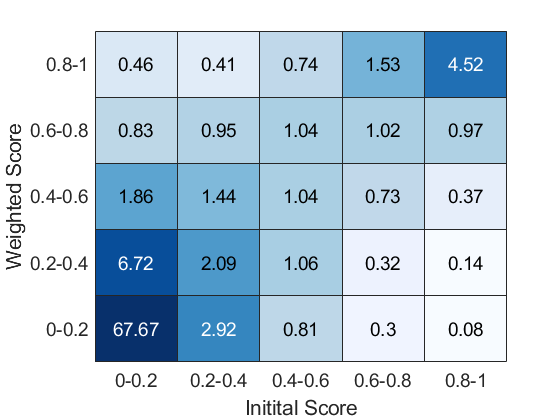

scR=objectTableComp.scoreWeightedRand;
scP=objectTableComp.scoreWeightedPref;
ng=length(scP);
figure
edj=0:0.2:1;
edj(end)=1.01;
len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((scP>=edj(i) & scP<edj(i+1)) & ...
            (scR>=edj(j) & scR<edj(j+1)) );
    end
end
 
 cdata=cdata./ng.*100;
 cdata= round(cdata.*100)/100;
 lab={'0-0.2' '0.2-0.4' '0.4-0.6' '0.6-0.8' '0.8-1'};
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
%caxis([0 4 ])
colorbar('off')
colormap(brewermap(256,'Blues'))
ht.xlabel('Random')
ht.ylabel('Preferred')
ht.FontSize=14;
ht.xlabel('Initital Score')
ht.ylabel('Weighted Score')
ht.ColorScaling='log';
ht.ColorLimits=[-1.5 2.5];
ht.NodeChildren(3).XAxis.Label.Interpreter = 'latex';
ht.NodeChildren(3).XAxis.Label.FontSize=20;
ht.NodeChildren(3).YAxis.Label.Interpreter = 'latex';
ht.NodeChildren(3).YAxis.Label.FontSize=20;

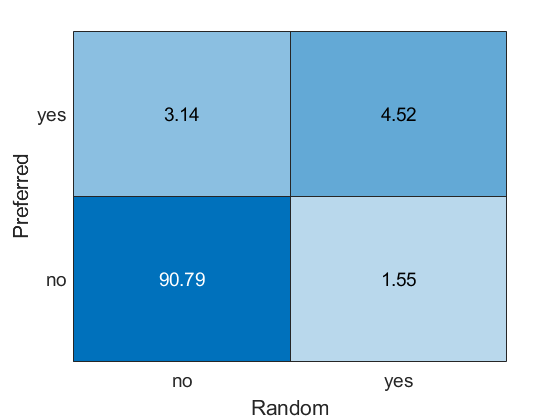







jfThresh=0.8;
jfCJF=scP>=jfThresh;
jf50=scR>=jfThresh;



jfdata=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./ng*100;
jfdata= round(jfdata.*100)/100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 8])
colorbar('off')
ht.xlabel('Random')
ht.ylabel('Preferred')

fprintf("total agreement on what is or isn't JF (score>=%s)= %s %% \n",...
   num2str(jfThresh), num2str(jfdata(1,2)+jfdata(2,1)))

total agreement on what is or isn't JF (score>=0.8)= 95.31 % 




fprintf("Number of PhaseI JF (score>=%s)= %s (%s %%) \n",...
   num2str(jfThresh), num2str((ng/100.*(jfdata(2,2)+jfdata(1,2)))),num2str(((jfdata(2,2)+jfdata(1,2)))))

Number of PhaseI JF (score>=0.8)= 531.8534 (6.07 %) 



fprintf("Number of PhaseII JF (score>=%s)= %s (%s %%) \n",...
   num2str(jfThresh), num2str((ng/100.*(jfdata(1,1)+jfdata(1,2)))),num2str(((jfdata(1,1)+jfdata(1,2)))))

Number of PhaseII JF (score>=0.8)= 671.1692 (7.66 %) 


fprintf("Increase of JF due to different viewing angle:  %s\n",...
   num2str(100.*(jfdata(1,1)+jfdata(1,2))/(jfdata(2,2)+jfdata(1,2))))

Increase of JF due to different viewing angle:  126.1944


## repeat but with a threshold of 75% (score=15)

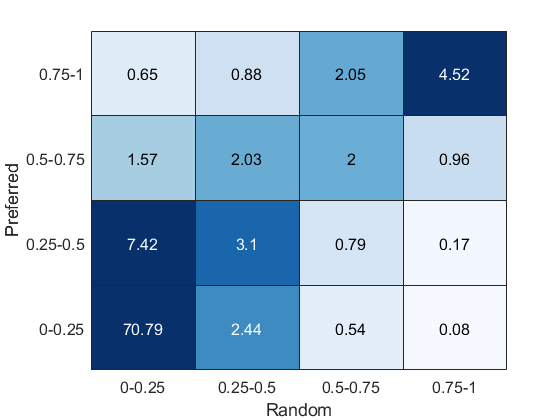



figure
edj=0:0.25:1;
edj(end)=1.01;
len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((scP>=edj(i) & scP<edj(i+1)) & ...
            (scR>=edj(j) & scR<edj(j+1)) );
    end
end
 
 cdata=cdata./ng.*100;
 cdata= round(cdata.*100)/100;
 lab={'0-0.25' '0.25-0.5' '0.5-0.75' '0.75-1'};
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
caxis([0 4 ])
colorbar('off')
colormap(brewermap(256,'Blues'))
ht.xlabel('Random')
ht.ylabel('Preferred')
ht.FontSize=12;

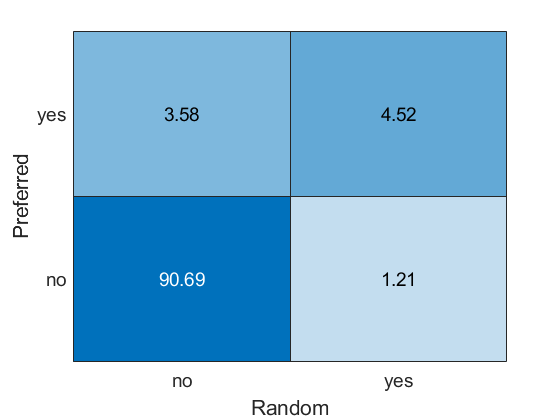



jfThresh=0.75;
jfCJF=scP/20>=jfThresh;
jf50=scR/20>=jfThresh;



jfdata=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./ng*100;
jfdata= round(jfdata.*100)/100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 8])
colorbar('off')
ht.xlabel('Random')
ht.ylabel('Preferred')

fprintf("total agreement on what is or isn't JF (score>=%s)= %s %% \n",...
   num2str(jfThresh), num2str(jfdata(1,2)+jfdata(2,1)))

total agreement on what is or isn't JF (score>=0.75)= 95.21 % 




fprintf("Number of PhaseI JF (score>=%s)= %s (%s %%) \n",...
   num2str(jfThresh), num2str((ng/100.*(jfdata(2,2)+jfdata(1,2)))),num2str(((jfdata(2,2)+jfdata(1,2)))))

Number of PhaseI JF (score>=0.75)= 502.0626 (5.73 %) 



fprintf("Number of PhaseII JF (score>=%s)= %s (%s %%) \n",...
   num2str(jfThresh), num2str((ng/100.*(jfdata(1,1)+jfdata(1,2)))),num2str(((jfdata(1,1)+jfdata(1,2)))))

Number of PhaseII JF (score>=0.75)= 709.722 (8.1 %) 


fprintf("Increase of JF due to different viewing angle:  %s\n",...
   num2str(100.*(jfdata(1,1)+jfdata(1,2))/(jfdata(2,2)+jfdata(1,2))))

Increase of JF due to different viewing angle:  141.3613
